# Bayesian Linear Regression

Be the model $y = a_1 x + a_2 \\
t = y + \xi$ where $\xi$ is the noise.

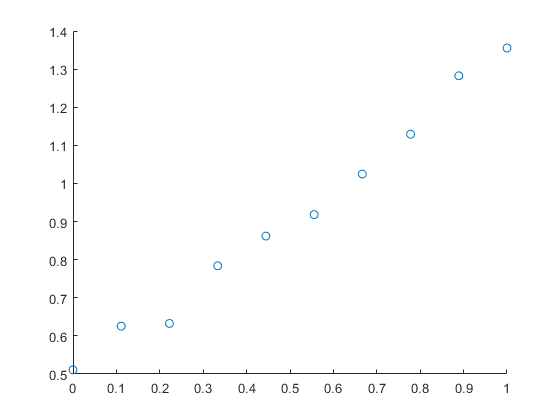

close all; clear all;
N = 10;
x = linspace(0,1,N).';
a0 = 0.5; a1 = 0.8;
y = a1*x+a0;
ns = normrnd(0,0.02,size(x));
t = y + ns;
scatter(x,t);

Defining $\phi_i(x)$

phi = @(x,i) (x^i);

Defining $\Phi$

M = 3;
P = [];
for i = 1:M
    Paux = arrayfun(@(x) phi(x,i),x);
    P = [P,Paux];
end

Calculating the $\mathbf{W}_{ML}$

Wml = pinv(P)*t;

Defining the parameter $\beta$ by the equation

$- \ln p(\mathbf{w}|\mathbf{x},\mathbf{t},\alpha,\beta) = -\frac{\beta}{2} \sum^N_{n=1}\left\{y(x_n,\mathbf{w}-t_n) \right\}^2 - \frac{N}{2} \ln \beta + \frac{N}{2} \ln 2 \pi - \frac{M+1}{2} \ln \left(\frac{2\pi}{\alpha}\right) + \frac{\alpha}{2} \mathbf{w}^T\mathbf{w}$ so, if $\frac{\partial}{\partial \beta} -\ln p(\mathbf{w_{ML}}|\mathbf{x},\mathbf{t},\alpha,\beta) = 0$ this means that$0 = -\frac{1}{2} \sum^N_{n=1}\left\{y(x_n,\mathbf{w_{ML}}-t_n) \right\}^2 - \frac{N}{2\beta} \Rightarrow \frac{1}{\beta_{ML}} =  \sum^N_{n=1}\left\{y(x_n,\mathbf{w_{ML}}-t_n) \right\}^2$

beta = sum(((P*Wml)-t).^2)^(-1);

If we define $\alpha = 1$

alpha = 1000;
Paux = P.'*P;
Sinv = alpha*eye(size(Paux)) + beta*Paux;
m = beta*(Sinv\P.'*t);

Defining the posterior gaussian distribution

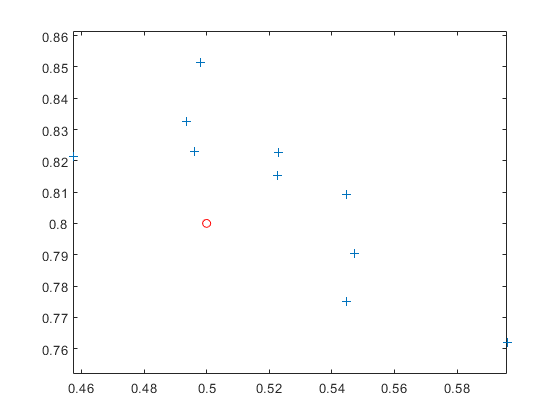

mu = [a0 a1];
Sigma = (alpha)^(-1)*eye(2);
w = mvnrnd(mu,Sigma,10); 
plot(w(:,1),w(:,2),'+'); axis equal; hold on;
plot(a0,a1,'ro'); hold off;

Plot the p

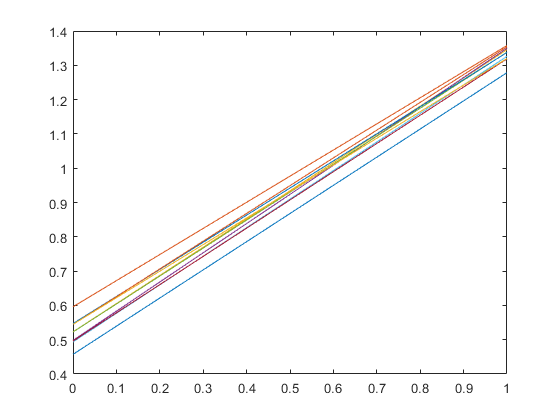

xx = linspace(0,1,100);
yt = w(:,2)*xx + w(:,1);
plot(xx,yt);